# Train Landcover Network

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads training and testing data.

rng(123)
load ../data/satData.mat

This code creates the architecture.

layers = [  imageInputLayer([28 28 4])
            convolution2dLayer(3, 20)
            reluLayer()
            maxPooling2dLayer(3)
            fullyConnectedLayer(6)
            softmaxLayer()
            classificationLayer()]

layers =   7×1 Layer array with layers:

     1   ''   Image Input             28×28×4 images with 'zerocenter' normalization
     2   ''   2-D Convolution         20 3×3 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   2-D Max Pooling         3×3 max pooling with stride [1  1] and padding [0  0  0  0]
     5   ''   Fully Connected         6 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

This code sets preliminary training options.

options = trainingOptions("sgdm", "MaxEpochs", 2, "InitialLearnRate", 0.0001);

## Task 1

You can use the `"Plots"` option to monitor network training.

`trainingOptions``(``"Plots"``,``"training-progress"``)`

options = trainingOptions("sgdm", "MaxEpochs", 2, "InitialLearnRate", 0.0001, "Plots", "training-progress");

## Train the network

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       10.16% |      39.5238 |      1.0000e-04 |
|       2 |          46 |       00:00:14 |       85.16% |       3.4000 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


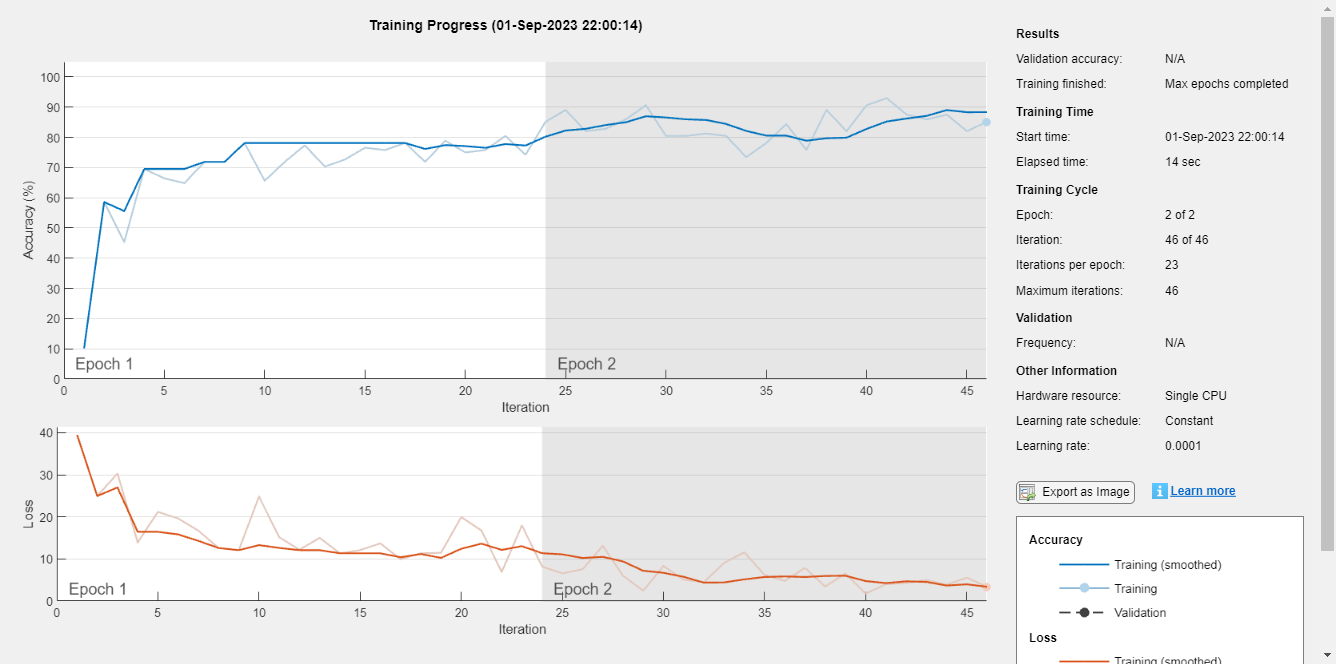

net = trainNetwork(XTrain, YTrain, layers, options);